% Chương trình P5_1

% Tính đáp ứng tần số của hệ thống LTI

clf;

% Tính các mẫu tần số của đáp ứng tần số

w=0:8*pi/511:2*pi;

num = [1/8 1/8 1/8 1/8 1/8 1/8 1/8];den = 1 % [1 -0.6];

den = 1

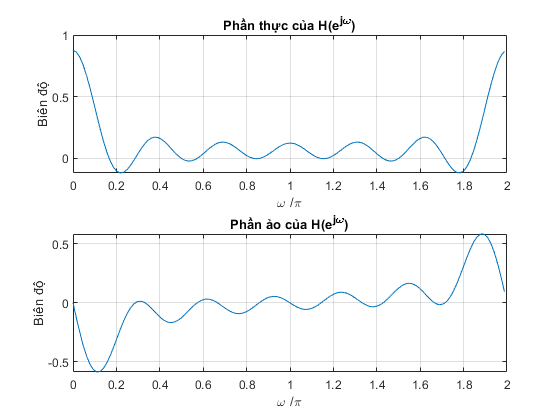


h = freqz(num, den, w);

% Vẽ đáp ứng tần số

figure(1)

subplot(2,1,1)

plot(w/pi,real(h));
grid 

title('Phần thực của H(e^{j\omega})')

xlabel('\omega /\pi');

ylabel('Biên độ');

subplot(2,1,2)

plot(w/pi,imag(h));grid

title('Phần ảo của H(e^{j\omega})')
xlabel('\omega /\pi');

ylabel('Biên độ');

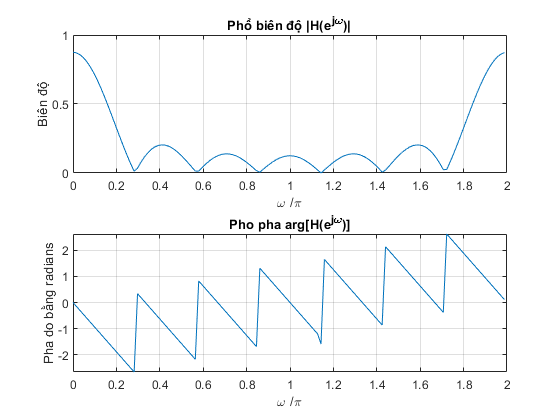


figure(2)

subplot(2,1,1)

plot(w/pi,abs(h));
grid

title('Phổ biên độ |H(e^{j\omega})|')

xlabel('\omega /\pi');

ylabel('Biên độ');

subplot(2,1,2)

plot(w/pi,angle(h));

grid 

title('Pho pha arg[H(e^{j\omega})]')

xlabel('\omega /\pi');

ylabel('Pha do bằng radians');

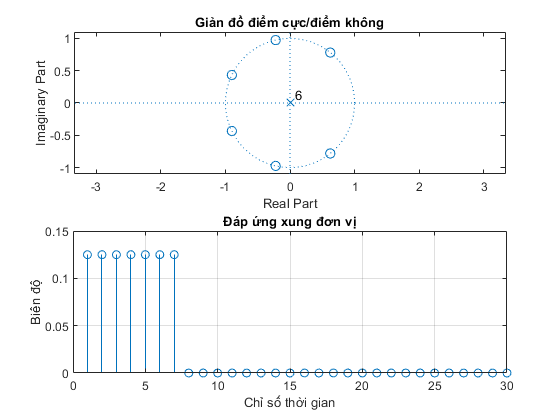


%Tính và vẽ đáp ứng xung đơn vị

figure(3)

h=impz(num,den, 30);

subplot(2,1,2);

stem(h);
grid

xlabel('Chỉ số thời gian'); ylabel('Biên độ');

title('Đáp ứng xung đơn vị');

% Tính và vẽ giản do diem cuc điểm không của hệ thống

subplot(2,1,1)

zplane(num,den);

title('Giản đồ điểm cực/điểm không');